# Task 1

disp("Task 1")

Task 1


p1 = [1 1 0 0 1 3];
p2 = [1 2 1 -10];
answer = conv(p1,p2);
disp(poly2sym(answer))

$$x^{8}+3\,x^{7}+3\,x^{6}-9\,x^{5}-9\,x^{4}+5\,x^{3}+7\,x^{2}-7\,x-30$$

## Task 2

disp("Task 2")

Task 2


p1 = [1 0 0 1 0 0 1 0 -1];
p2 = [1 0 2 -1];
[d,r] = deconv(p1,p2);
disp(poly2sym(d))

$$x^{5}-2\,x^{3}+2\,x^{2}+4\,x-6$$

## Task 3

disp("Task 3")

Task 3


p1 = [1 0 1 1 -3 -2 -16 -1];
p2 = [1 0 -116 1];
[d,r] = deconv(p1,p2);
disp(poly2sym(r))

$$-119\,x^{2}+1573988\,x-13570$$

## Task 4

disp("Task 4")

Task 4


p1 = [1 0 0 1 4 2 3 0 1 3];
p2 = [0 0 0 0 3 0 0 2 -3 -9];
res = p1 + p2;
disp(poly2sym(res))

$$ans = x^{9}+x^{6}+7\,x^{5}+2\,x^{4}+3\,x^{3}+2\,x^{2}-2\,x-6$$

## Task 5

disp("Task 5")

Task 5


p1 = [0 1 2 0 0 4 2 0 3 3];
p2 = [1 0 0 0 0 0 0 0 2 0];
res = p1 - p2;
disp(poly2sym(res))

$$-x^{9}+x^{8}+2\,x^{7}+4\,x^{4}+2\,x^{3}+x+3$$

## Task 6

disp("Task 6")

Task 6


p = [2 3 0 1 -10 -1 1024];
res = polyder(p);
disp(poly2sym(res))

$$12\,x^{5}+15\,x^{4}+3\,x^{2}-20\,x-1$$

## Task 7

disp("Task 7")

Task 7


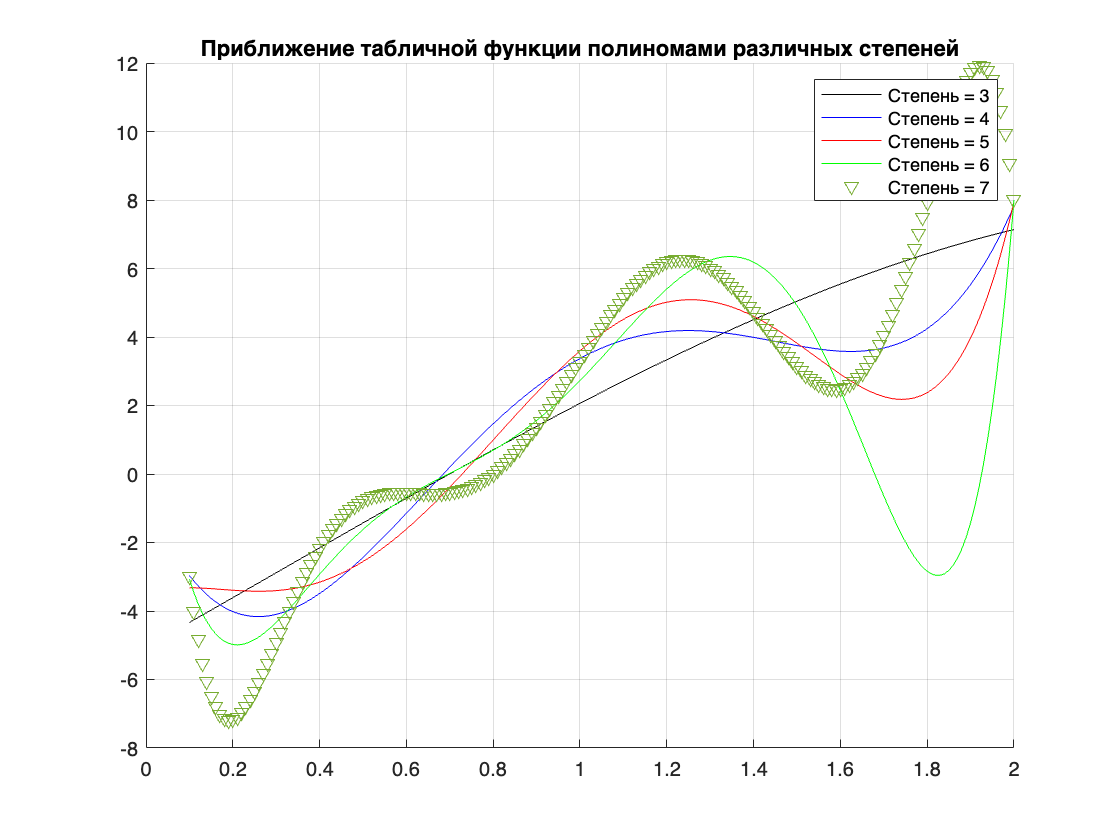

figure;
x = [0.1 0.3 0.4 0.6 0.7 0.9 1.0 1.3 1.6 2.0];
y = [-3 -5 -2 -1 0 1 3.5 6 2.5 8];

p3 = polyfit(x, y, 3);
p4 = polyfit(x, y, 4);
p5 = polyfit(x, y, 5);
p6 = polyfit(x, y, 6);
p7 = polyfit(x, y, 7);

t = 0.1:0.01:2;

P3 = polyval(p3, t);
P4 = polyval(p4, t);
P5 = polyval(p5, t);
P6 = polyval(p6, t);
P7 = polyval(p7, t);

hold on;
grid on;
plot(t, P3, "k", t, P4, "b", t, P5, "r", t, P6, "g", t, P7, "v")
legend("Степень = 3", "Степень = 4", "Степень = 5", "Степень = 6", "Степень = 7")
title("Приближение табличной функции полиномами различных степеней")

## Task 8

disp ("Task 8")

Task 8


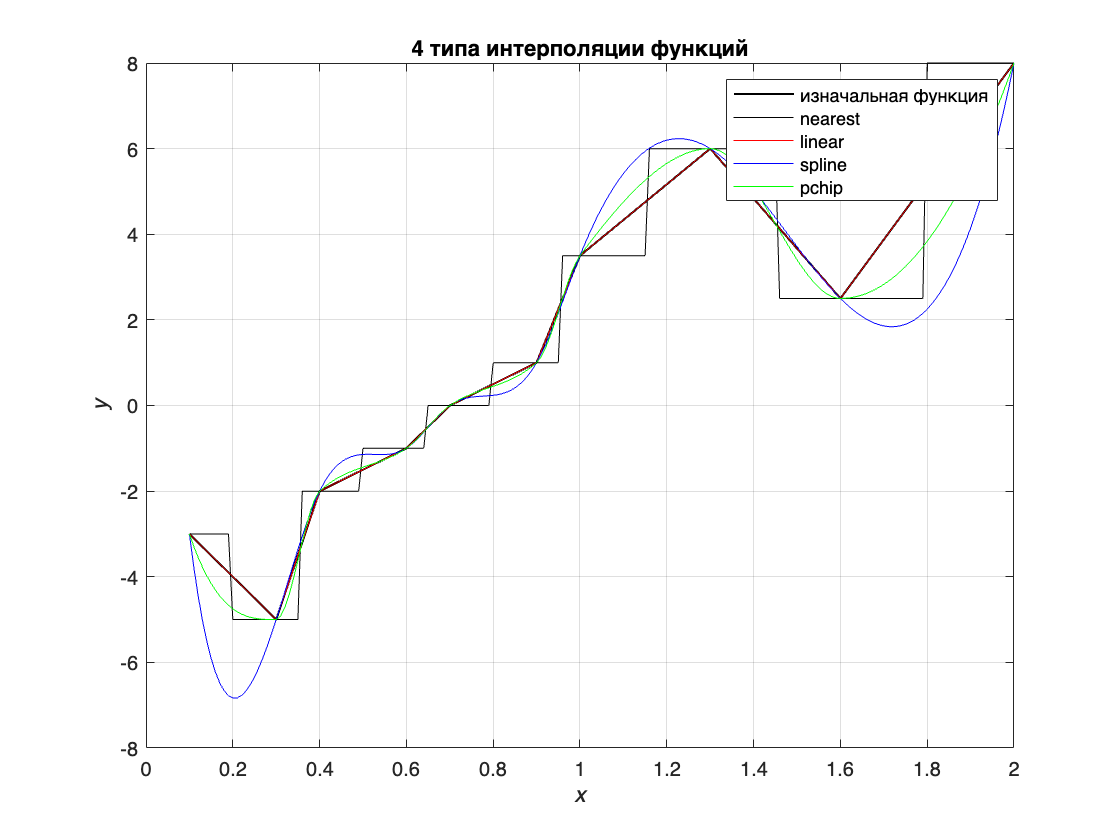

figure;
x = [0.1 0.3 0.4 0.6 0.7 0.9 1.0 1.3 1.6 2.0];
y = [-3 -5 -2 -1 0 1 3.5 6 2.5 8];
plot(x, y, 'k', LineWidth = 1)
xi = x(1):0.01:x(10);

nearpoints = interp1(x, y, xi, 'nearest');
linear = interp1(x, y, xi, 'linear');
splines = interp1(x, y, xi, 'spline');
ypchip = interp1(x, y, xi, 'pchip');

hold on;
grid on;

plot(xi, nearpoints, "k", xi, linear, "r", xi, splines, "b", xi, ypchip, "g")
title("4 типа интерполяции функций")
xlabel("\itx")
ylabel("\ity")
legend("изначальная функция", "nearest", "linear", "spline", "pchip")

## Task 9

disp ("Task 9")

Task 9


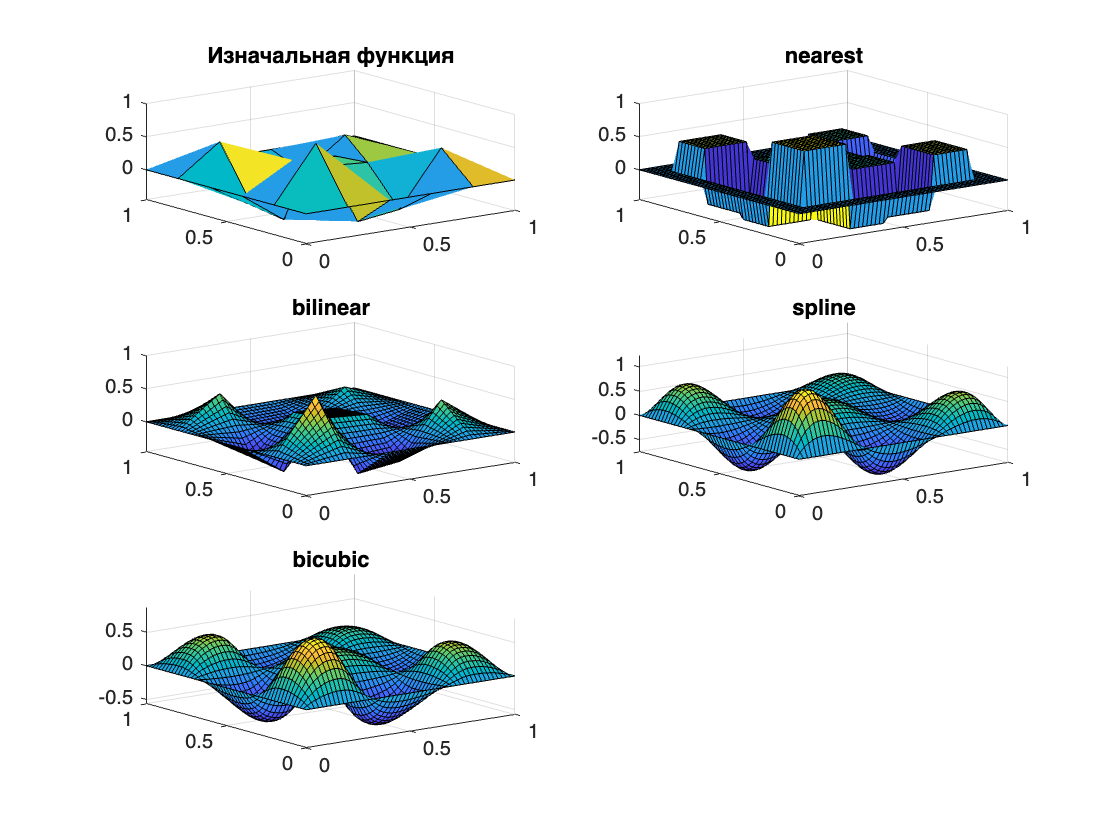

figure;
[X, Y] = meshgrid(0:0.2:1);

Z = sin(3*pi*X).*sin(3*pi*Y).*exp(-X.^2 - Y.^2);

[Xi, Yi] = meshgrid(0:0.02:1);

Cnearest = interp2(X, Y, Z, Xi, Yi, 'nearest');
Cbilinear = interp2(X, Y, Z, Xi, Yi, 'bilinear');
Csplines = interp2(X, Y, Z, Xi, Yi, 'spline');
Cbicubic = interp2(X, Y, Z, Xi, Yi, 'bicubic');


subplot(3, 2, 1)
surfl(X, Y, Z)
title("Изначальная функция")

subplot(3, 2, 2)
surf(Xi, Yi, Cnearest)
title("nearest")

subplot(3, 2, 3)
surf(Xi, Yi, Cbilinear)
title("bilinear")

subplot(3, 2, 4)
surf(Xi, Yi, Csplines)
title("spline")

subplot(3, 2, 5)
surf(Xi, Yi, Cbicubic)
title("bicubic")